## Case Study 3 –  The CG algorithm 

 1. Discretization of 2D Poisson equation (Q 3.1) 2. Serial Conjugate Gradient solver (Q3.2) 3. Convergence analysis on dense systems (Q3.3)

## Part 3.1 –  Basics: The Poisson problem: I worte the method in the written document.

## Part 3.2 – Serial CG Solver for Sparse System

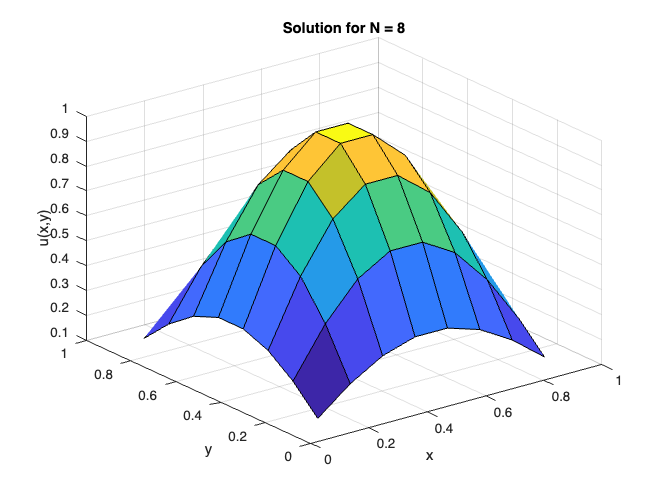

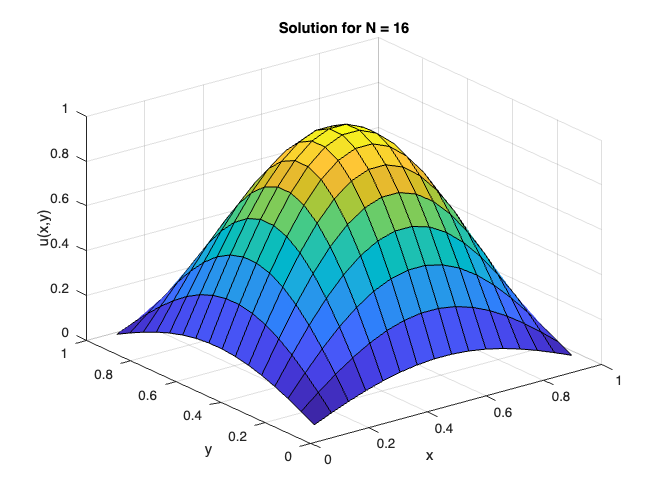

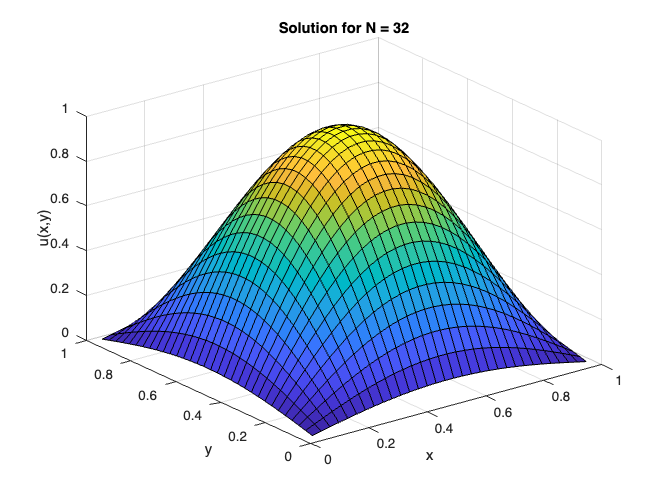

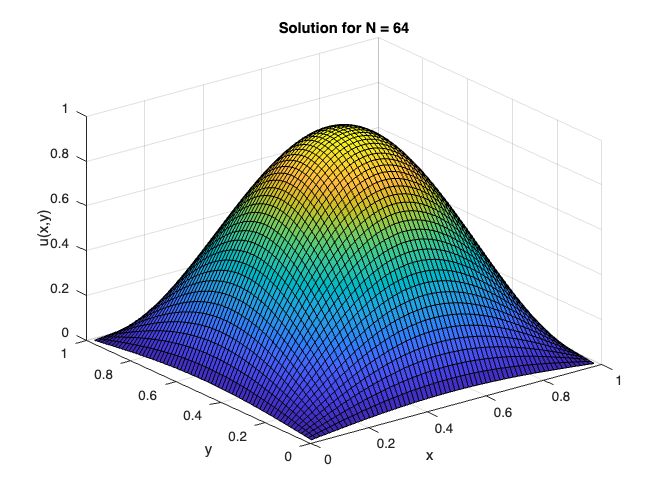

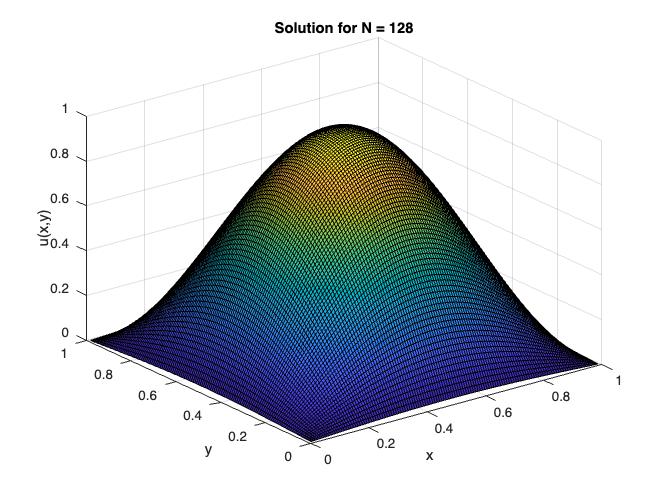

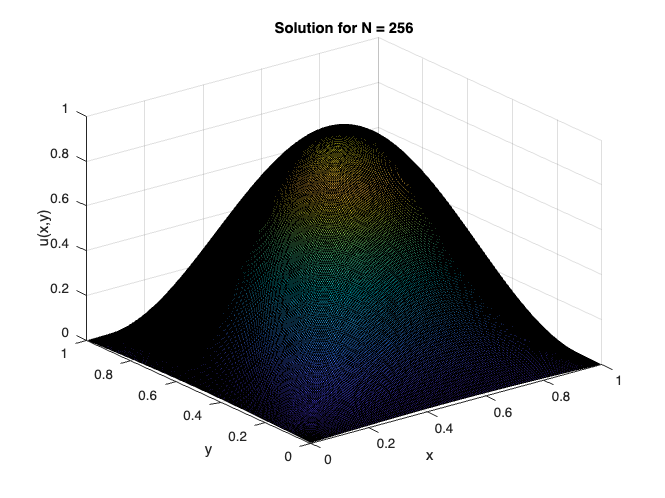

clear;clc
% Conjugate Gradient function
function [x, iter, res_hist] = my_cg(A, b, tol, max_iter)
    x = randn(size(b));
    r = b - A * x;
    p = r;
    res_old = r' * r;
    res_hist = sqrt(res_old);
    iter = 0;

    while sqrt(res_old) > tol && iter < max_iter
        Ap = A * p;
        alpha = res_old / (p' * Ap);
        x = x + alpha * p;
        r = r - alpha * Ap;
        res_new = r' * r;
        beta = res_new / res_old;
        p = r + beta * p;
        res_old = res_new;
        res_hist(end+1) = sqrt(res_new);
        iter = iter + 1;
    end
end
    Ns = [8, 16, 32, 64, 128,256];
    tol = 1e-8;
    max_iter = 10000;
    results = [];
  
 
    % Loop over different grid sizes
    for i = 1:length(Ns)
        N = Ns(i);
        h = 1 / (N + 1);
        x = linspace(h, 1 - h, N);
        [X, Y] = meshgrid(x, x);

        % Right-hand side function as specified in assignment
         f = @(x, y) 2*pi^2 * sin(pi*x) .* sin(pi*y);

        b = h^2 * f(X, Y);
        b = reshape(b, [], 1);

        % Build 2D Laplacian matrix using Kronecker product
        e = ones(N, 1);
        T = spdiags([-e 2*e -e], -1:1, N, N);
        I = speye(N);
        A = kron(I, T) + kron(T, I);

        % Start timer
        tic;
        [x_cg, iters, res_hist] = my_cg(A, b, tol, max_iter);
        elapsed = toc;

        results = [results; N, iters, elapsed];

        % Plot solution 
        if N <= 256
            figure;
            surf(X, Y, reshape(x_cg, N, N));
            title(['Solution for N = ', num2str(N)]);
            xlabel('x');ylabel('y');zlabel('u(x,y)');
        end
    end


    % Display summary
    disp(array2table(results, 'VariableNames', {'N', 'Iterations', 'Time_sec'}));

     N     Iterations    Time_sec 
    ___    __________    _________

      8        29         0.056029
     16        56        0.0018936
     32       111        0.0052069
     64       211        0.0089982
    128       412         0.056248
    256       767          0.39015



## Part 3.3 – CG Convergence on Dense Matrix System

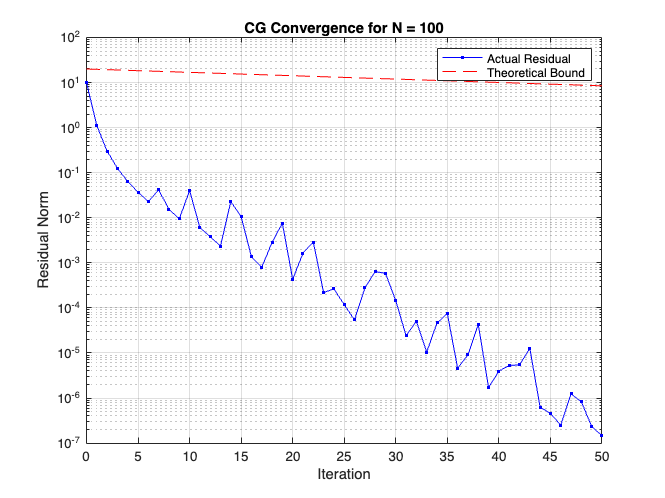

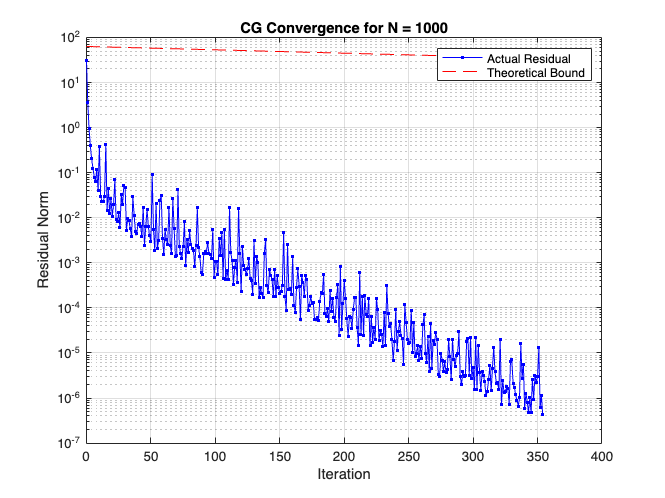

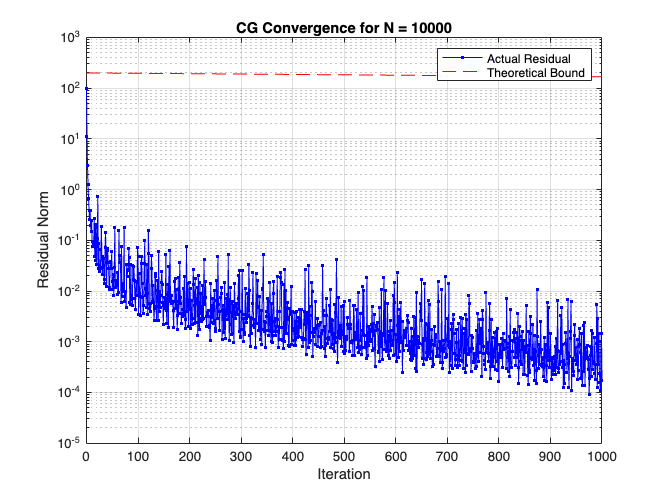

Ns = [100, 1000, 10000];
tol = sqrt(eps('double'));
max_iter = 1000;

for i = 1:length(Ns)
    N = Ns(i);
    A = toeplitz((N - (0:N-1)) / N);
    b = ones(N,1);
    x = zeros(N,1);
    r = b - A*x; p = r;
    r0_norm = norm(r);
    res_hist = r0_norm;

    for k = 1:max_iter
        Ap = A * p;
        alpha = (r' * r) / (p' * Ap);
        x = x + alpha * p;
        r_new = r - alpha * Ap;
        res_norm = norm(r_new);
        res_hist(end+1) = res_norm;
        if res_norm <= max(tol * r0_norm, 0)
            break;
        end
        beta = (r_new' * r_new) / (r' * r);
        p = r_new + beta * p;
        r = r_new;
    end

    eigvals = eig(A);
    kappa = max(eigvals) / min(eigvals);
    bound = 2 * ((sqrt(kappa)-1)/(sqrt(kappa)+1)).^(0:length(res_hist)-1) * r0_norm;

    figure;
    semilogy(0:length(res_hist)-1, res_hist, 'b.-', ...
             0:length(bound)-1, bound, 'r--');
    legend('Actual Residual', 'Theoretical Bound');
    title(['CG Convergence for N = ', num2str(N)]);
    xlabel('Iteration'); ylabel('Residual Norm');
    grid on;
end